**Task 2**

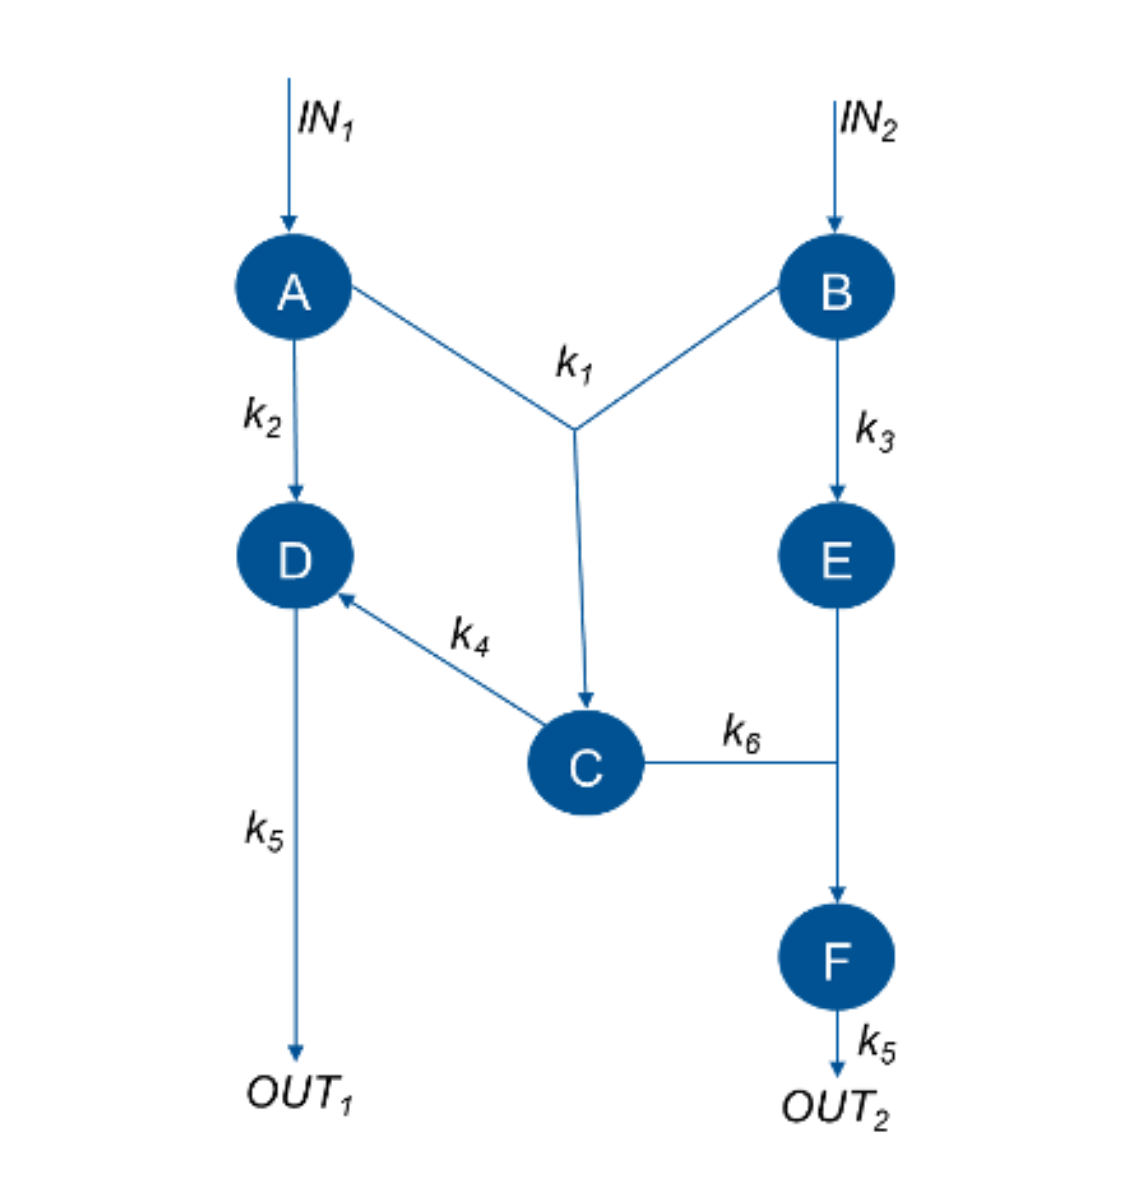

a. Integrate the kinetic parameters (k1 to k6) into your MATLAB script using the function load.

temp = load("pEuler2.mat");
k = [temp.p.k1, temp.p.k2, temp.p.k3, temp.p.k4, temp.p.k5, temp.p.k6];
% If you want to launch from the GitHub - use this values for k
% k = [0.7500, 1.0000, 0.6000, 0.2000, 1.5000, 1.2500]

b. Writedown the differential equations for the chemical components (A,B,C,D,E,F) as well as for the outputs of the system (OUT1 and OUT2). Use them to set-up Euler’s method for this system (SEE THE LOCAL FUNCTIONS SECTION AT THE BOTTOM OF THE SCRIPT)

c. Simulate the systems dynamics in the time range [0,10] for constant input values IN1 = 1 and IN2 = 0.5. All chemical components should be initialized at 0, except for A, which should have an initial value of 0.5 .

IN = [1, 0.5];
dt = 0.01;
timeSpan = 0:dt:10;
stateMatrix = zeros(8, length(timeSpan));
stateMatrix(1, 1) = 0.5;

for i = 2:length(timeSpan)
    
    stateMatrix(:, i) = eulerSystem(stateMatrix(:, i-1), k, IN, dt);

end

d. Plot the results of the simulation in two separate figures, one for the chemical components and one for the output values.

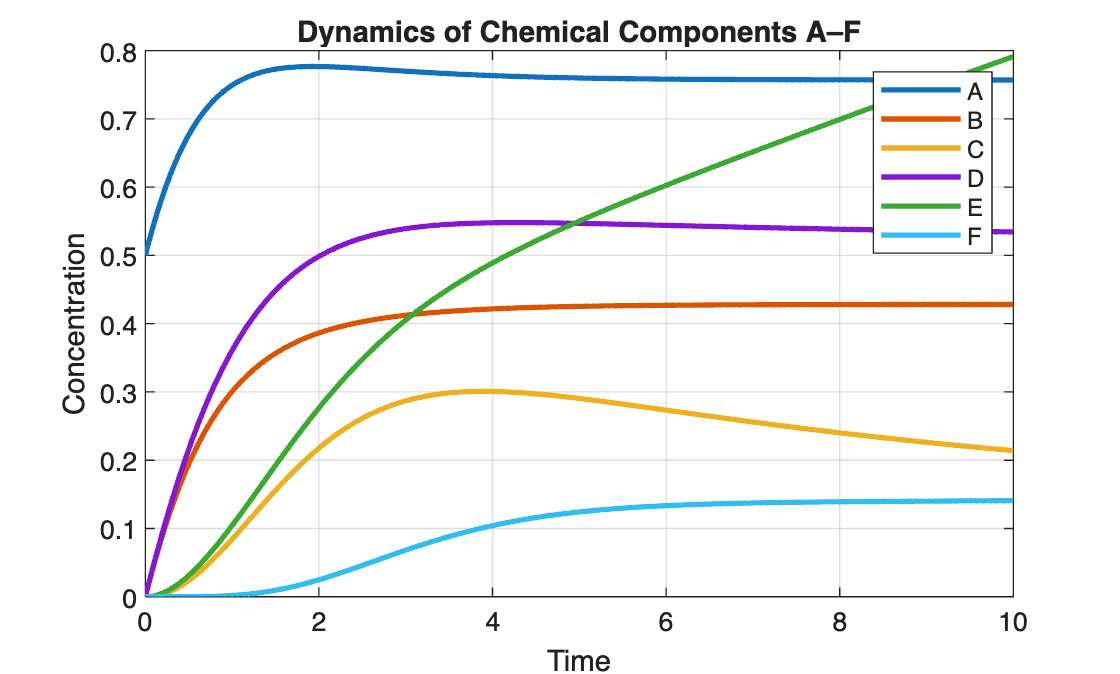

figure;
plot(timeSpan, stateMatrix(1:6, :), 'LineWidth', 2);
title('Dynamics of Chemical Components A–F');
xlabel('Time');
ylabel('Concentration');
legend('A','B','C','D','E','F');
grid on;

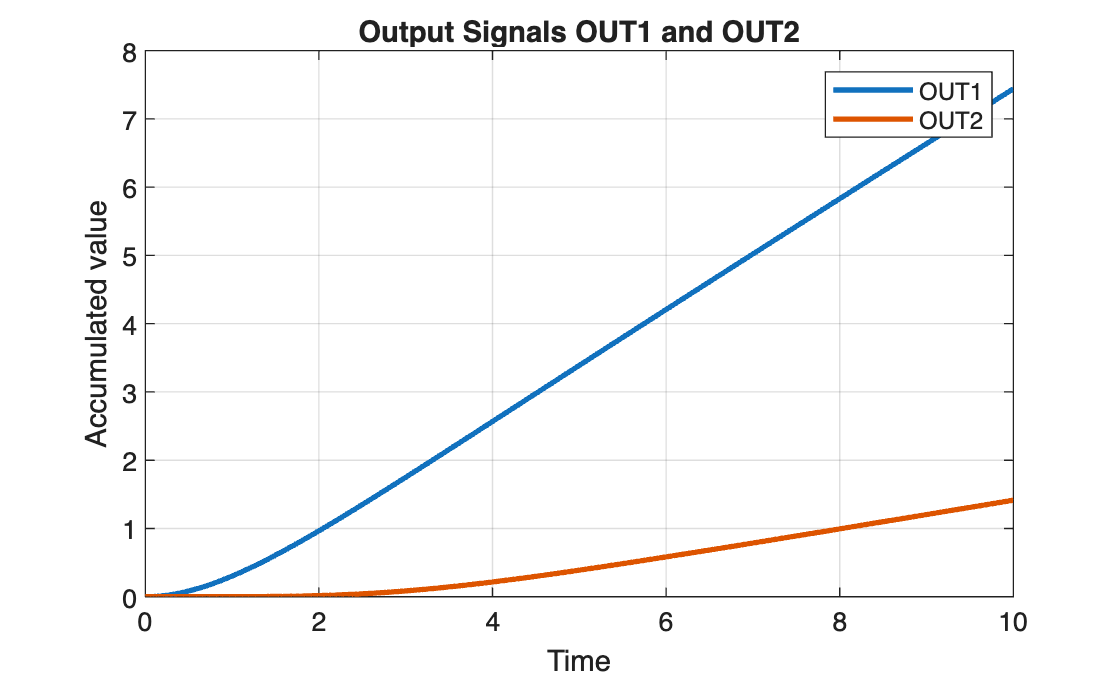


figure;
plot(timeSpan, stateMatrix(7:8, :), 'LineWidth', 2);
title('Output Signals OUT1 and OUT2');
xlabel('Time');
ylabel('Accumulated value');
legend('OUT1','OUT2');
grid on;

e. Now, perform the same simulation, but with limited inputs. In this case, IN1 = 1 only in the time frame [0,2], whereas IN2 = 0.5 only in the time frame [0.5 , 2.5]. In the remaining time frames, IN1 and IN2 equal 0. All other characteristics re- main the same. Plot the results of the simulation. According to your simulation, which compounds are most affected by this limited input? How does the output change upon the limited input?

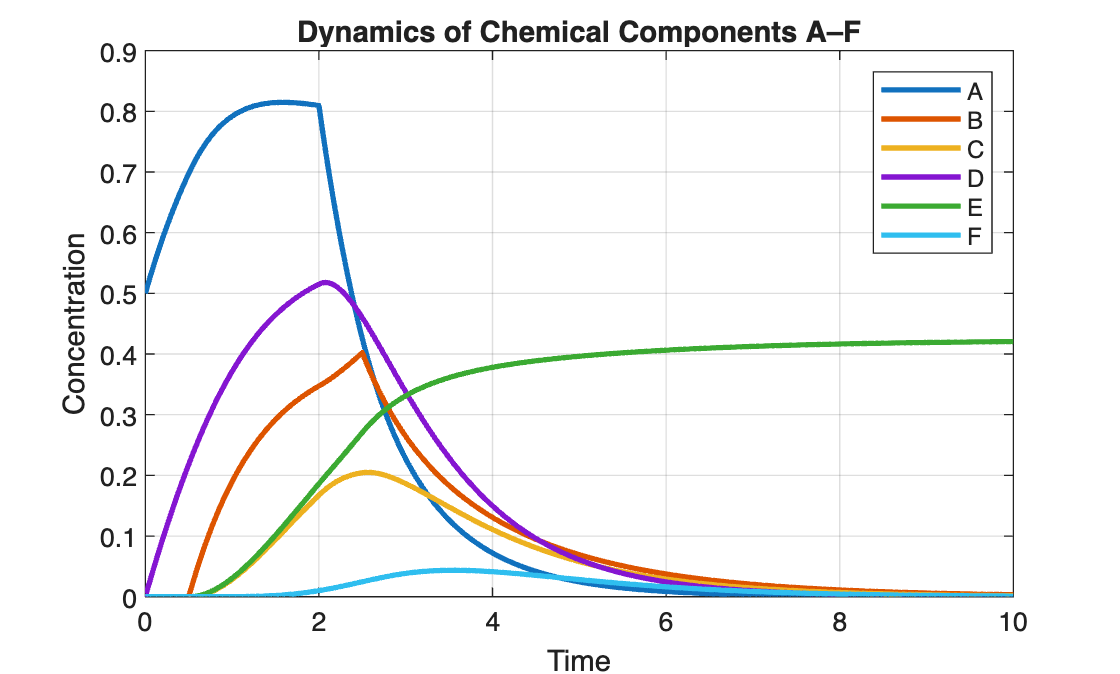

stateMatrix2 = zeros(8, length(timeSpan));
stateMatrix2(1, 1) = 0.5;

for i = 2:length(timeSpan)

    if timeSpan(i) <= 0.5
        IN = [1, 0];
    elseif timeSpan(i) > 0.5 && timeSpan(i) <= 2
        IN = [1, 0.5];
    elseif timeSpan(i) > 2 && timeSpan(i) <= 2.5
        IN = [0, 0.5];
    else
        IN = [0, 0];
    end
    
    stateMatrix2(:, i) = eulerSystem(stateMatrix2(:, i-1), k, IN, dt);

end


figure;
plot(timeSpan, stateMatrix2(1:6, :), 'LineWidth', 2);
title('Dynamics of Chemical Components A–F');
xlabel('Time');
ylabel('Concentration');
legend('A','B','C','D','E','F');
grid on;

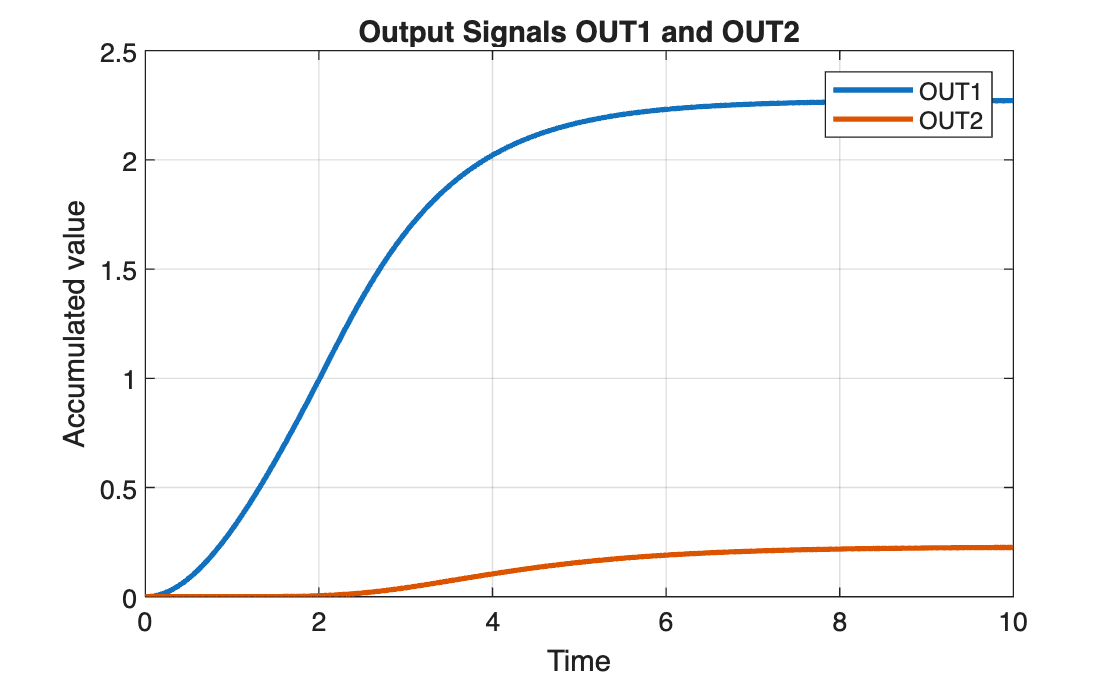



figure;
plot(timeSpan, stateMatrix2(7:8, :), 'LineWidth', 2);
title('Output Signals OUT1 and OUT2');
xlabel('Time');
ylabel('Accumulated value');
legend('OUT1','OUT2');
grid on;

**Most affected chemical components**

The components that are most affected by the limited input are:

	•	A and B, because they directly depend on the external inputs IN1 and IN2.

	•	Their concentrations rise only during the time windows when the inputs are active.

	•	As soon as the inputs drop to zero, both A and B immediately decrease.

	•	D, which is produced from A, is also strongly affected.

	•	Its peak occurs shortly after A reaches its maximum.

	•	After the input disappears, D declines rapidly.

	•	C, E, and F still rise for a short time due to the internal reactions, but their overall levels remain much lower than in the constant-input case.

This indicates that the transient supply of A and B is not enough to sustain high concentrations of downstream species.

**Changes in the output signals**

	•	OUT1 shows a strong response during the early phase (0–2.5), since it accumulates the degradation of D, which is directly influenced by A.

	•	After the inputs disappear, OUT1 reaches a plateau.

	•	OUT2 increases only slightly.

	•	Since F remains very small in the limited-input scenario, the amount of accumulated OUT2 is much lower than in the full-input simulation.

**Summary**

Limited inputs primarily affect the early-stage components (A, B, and D), and strongly reduce the formation of downstream products (C, E, F). Consequently, OUT1 accumulates noticeably, while OUT2 remains very small, reflecting the reduced production of F.

%% Local functions
function nextState = eulerSystem(currentState, k, IN, dt)


    A = currentState(1);
    B = currentState(2);
    C = currentState(3);
    D = currentState(4);
    E = currentState(5);
    F = currentState(6);

    nextState = [
        IN(1) - k(1) * A * B - k(2) * A;
        IN(2) - k(1) * A * B - k(3) * B;
        k(1) * A * B - k(4) * C - k(6) * C * E;
        k(2) * A + k(4) * C - k(5) * D;
        k(3) * B - k(6) * C * E;
        k(6) * C * E - k(5) * F;
        k(5) * D;
        k(5) * F;
     ];

    nextState = nextState * dt + currentState;

end